# Training Unit 5: ODE numerical solver

Fink Lucas / Teichtmeister Marcus, 28.10.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Derivation of the Analytical Solution of the Ordinary Differential Equation

The following ODE is given:


$$\frac{\textrm{dy}}{\textrm{dt}}=-\frac{y}{\tau \;}$$


First, the equation is multiplied by $\textrm{dt}$ and divided by $y$.


$$\frac{1}{y}\textrm{dy}=-\frac{1}{\tau \;}\textrm{dt}$$


Then integrated on both sides.


$$\int \;\frac{1}{y}\textrm{dy}=-\int \;\frac{1}{\tau \;}\textrm{dt}\to \ln \left(|y|\right)+C_1 =-\frac{t}{\tau \;}+C_2 \to \ln \left(|y|\right)=-\frac{t}{\tau \;}+C$$



$$y=e^{-\frac{t}{\tau \;}+C} =e^C e^{-\frac{t}{\tau \;}}$$


Which gives the function:


$$y=y_0 \;e^{-\frac{t}{\tau \;}}$$
    

## Implementing the analytical solution

PARAMETERS.y_0     = 1

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.t_0     = 0

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.t_final = 10

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.h       = 1

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.tau     = 2

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.N        = 10

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


## Implementing the Numerical Solution

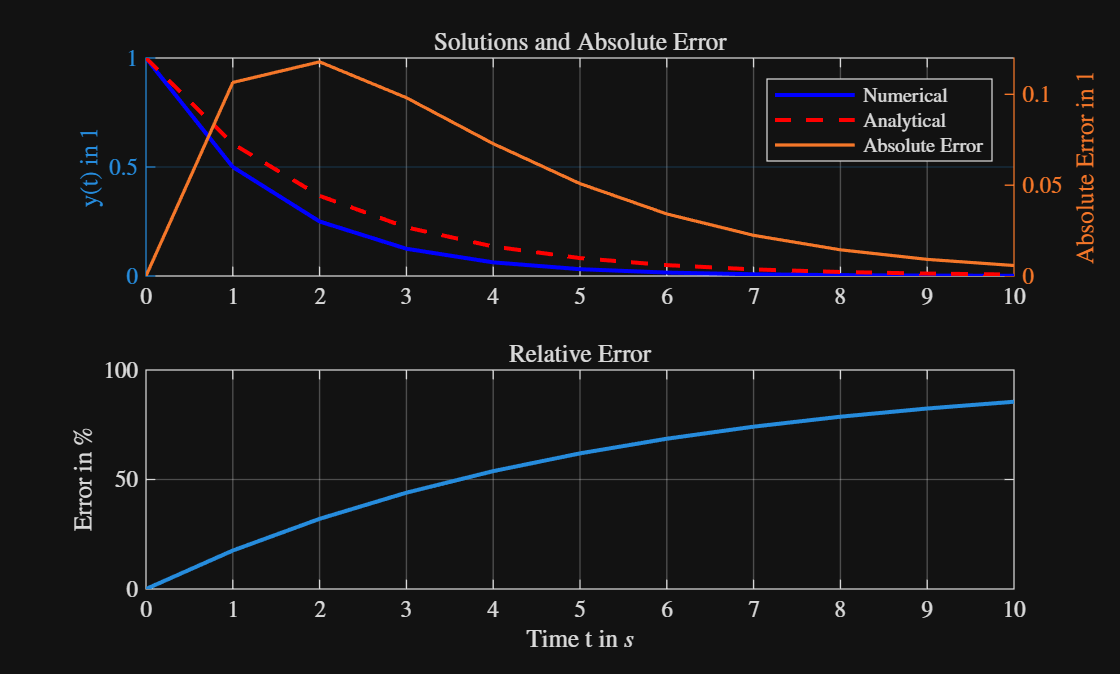

[t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

Results = table(t(:), y_num(:), y_exact(:), 'VariableNames', {'Time','y_Numerical','y_Analytical'});

[abs_error, mean_abs_error, rel_error, mean_rel_error] = computer_error(y_exact, y_num);

figure;
tiledlayout(2,1);

ax1 = nexttile;
yyaxis left
plot(t, y_num, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Numerical');
hold on
plot(t, y_exact, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
ylabel('y(t) in 1');
legend('Location','northeast');

yyaxis right
plot(t, abs_error, 'LineWidth', 1.2, 'DisplayName', 'Absolute Error');
ylabel('Absolute Error in 1');
grid on
title('Solutions and Absolute Error');

ax2 = nexttile;
plot(t, rel_error, 'LineWidth', 1.5, 'DisplayName', 'Relative Error');
xlabel('Time t in $s$');
ylabel('Error in $\%$');
grid on
title('Relative Error');

linkaxes([ax1, ax2],'x');

disp(['Mean relative error: ', num2str(mean_rel_error), '%']);

Mean relative error: 54.4251%


disp(['Mean absolute error: ', num2str(mean_abs_error)]);

Mean absolute error: 0.048371


## Error

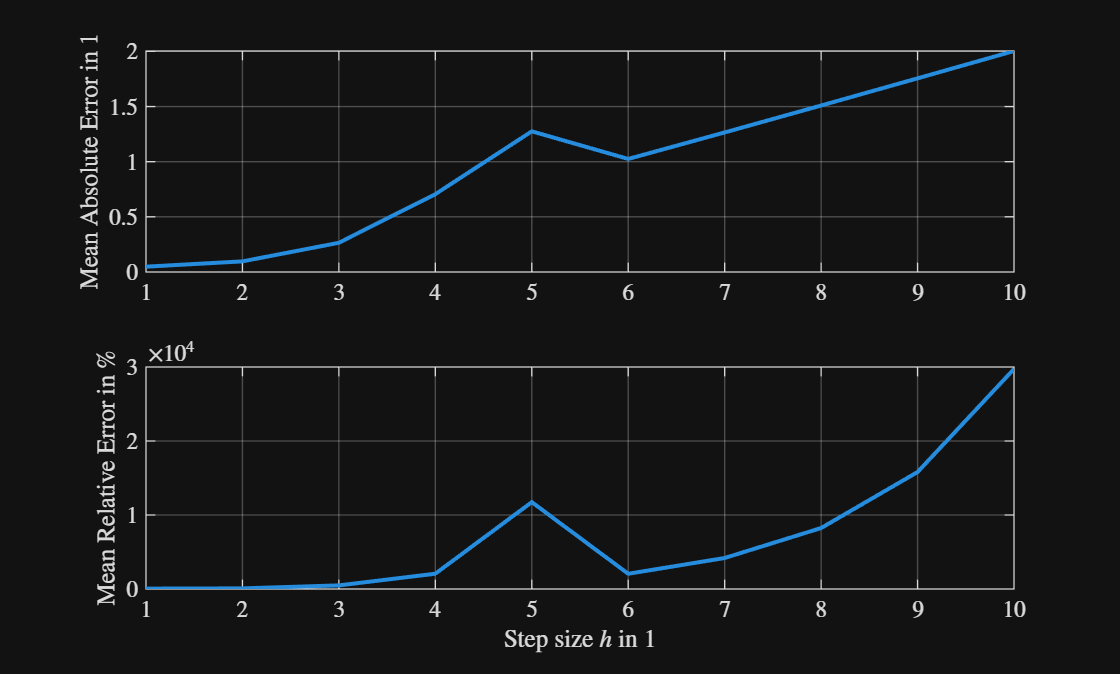

% Step sizes to test
h_values = linspace(1,10,10);

% Preallocate vectors for mean errors
mean_abs_errors = zeros(size(h_values));
mean_rel_errors = zeros(size(h_values));

% Loop over each step size
for i = 1:length(h_values)
    h = h_values(i);
    
    % Numerical solution
    [t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, h, PARAMETERS.t_0, PARAMETERS.t_final);
    
    % Exact solution
    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);
    
    % Compute errors
    [~, mean_abs_error, ~, mean_rel_error] = computer_error(y_exact, y_num);
    
    % Store mean errors
    mean_abs_errors(i) = mean_abs_error;
    mean_rel_errors(i) = mean_rel_error;
end

% Plot mean errors vs step size
figure;
tiledlayout(2,1)
pl1 = nexttile;
plot(h_values, mean_abs_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Absolute Error');
ylabel('Mean Absolute Error in 1');
grid on;

pl2 = nexttile;
plot(h_values, mean_rel_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Relative Error');
xlabel('Step size $h$ in 1');
ylabel('Mean Relative Error in $\%$');
grid on;

## Implementing a second solver

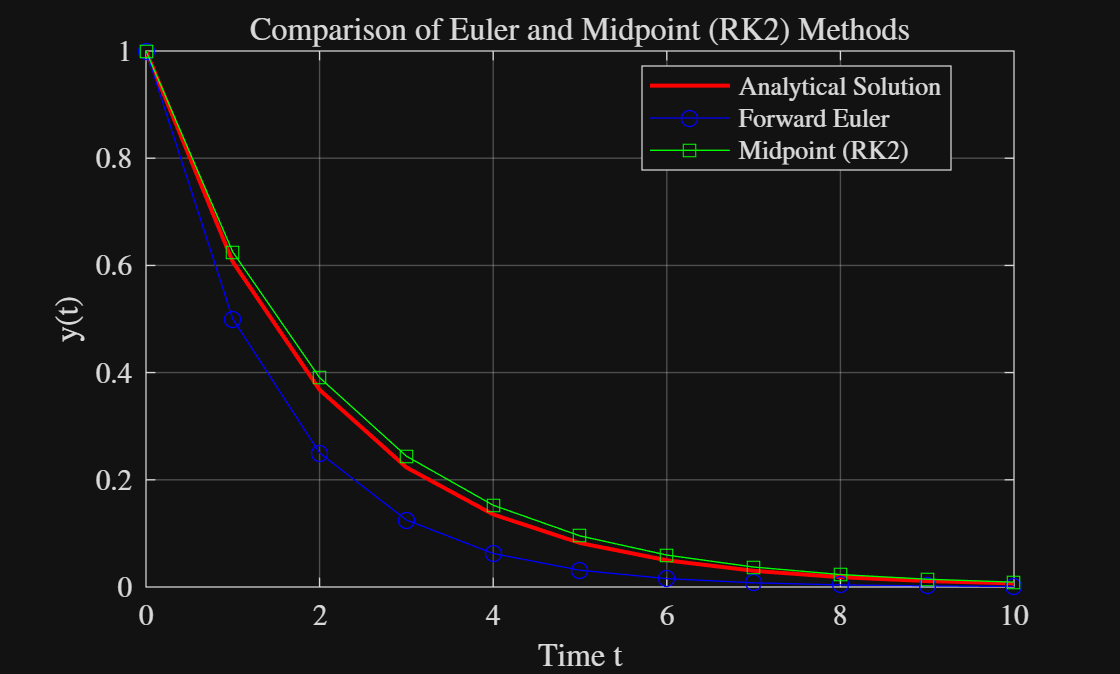

y_mid = zeros(1, PARAMETERS.N+1);
y_mid(1) = PARAMETERS.y_0;
f = @(t, y) -y / PARAMETERS.tau;
for k = 1:PARAMETERS.N
    k1 = f(t(k), y_mid(k));
    k2 = f(t(k) + PARAMETERS.h/2, y_mid(k) + (PARAMETERS.h/2)*k1);
    y_mid(k+1) = y_mid(k) + PARAMETERS.h * k2;
end


figure;
plot(t, y_exact, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Analytical Solution');
hold on;
plot(t, y_num, 'bo-', 'DisplayName', 'Forward Euler');
plot(t, y_mid, 'gs-', 'DisplayName', 'Midpoint (RK2)');
xlabel('Time t');
ylabel('y(t)');
title('Comparison of Euler and Midpoint (RK2) Methods');
legend('Location', 'best');
grid on;

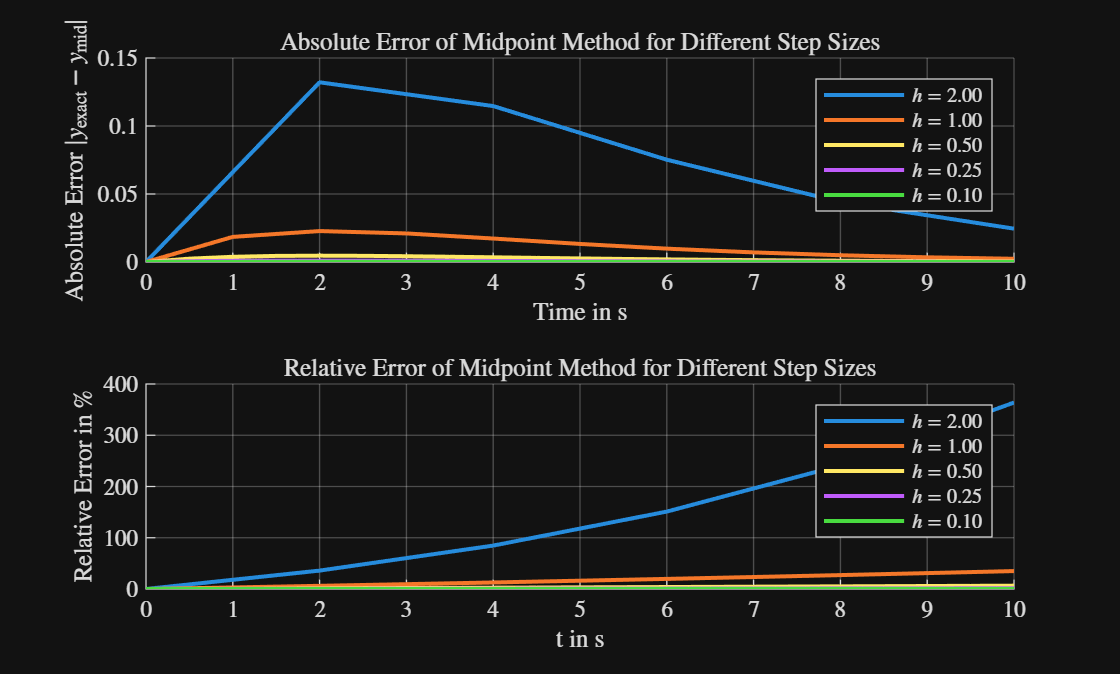

h_values = [2, 1, 0.5, 0.25, 0.1];
colors = lines(length(h_values)); 

figure;
tiledlayout(2, 1);

% ===== Tile 1: Absolute Error =====
ax1 = nexttile;
hold(ax1, 'on');
title(ax1, 'Absolute Error of Midpoint Method for Different Step Sizes');
xlabel(ax1, 'Time in s');
ylabel(ax1, 'Absolute Error $|y_{\mathrm{exact}} - y_{\mathrm{mid}}|$');
grid(ax1, 'on');

% ===== Tile 2: Relative Error =====
ax2 = nexttile;
hold(ax2, 'on');
title(ax2, 'Relative Error of Midpoint Method for Different Step Sizes');
xlabel(ax2, 't in s');
ylabel(ax2, 'Relative Error in $\%$');
grid(ax2, 'on');

% ===== Loop over step sizes =====
for i = 1:length(h_values)
    h = h_values(i);
    t = PARAMETERS.t_0:h:PARAMETERS.t_final;
    N = length(t);
    f = @(t, y) -y / PARAMETERS.tau;

    % Midpoint (RK2) solver
    y_mid = zeros(size(t));
    y_mid(1) = PARAMETERS.y_0;
    for k = 1:N-1
        k1 = f(t(k), y_mid(k));
        k2 = f(t(k) + h/2, y_mid(k) + (h/2)*k1);
        y_mid(k+1) = y_mid(k) + h * k2;
    end

    % Analytical solution
    y_exact = PARAMETERS.y_0 * exp(-t / PARAMETERS.tau);

    abs_error = abs(y_exact - y_mid);
    rel_error = abs((y_exact - y_mid) ./ y_exact) * 100;

    plot(ax1, t, abs_error, 'LineWidth', 1.5, 'Color', colors(i,:), ...
        'DisplayName', sprintf('$h = %.2f$', h));
    plot(ax2, t, rel_error, 'LineWidth', 1.5, 'Color', colors(i,:), ...
        'DisplayName', sprintf('$h = %.2f$', h));
end

legend(ax1, 'Location', 'northeast');
legend(ax2, 'Location', 'northeast');

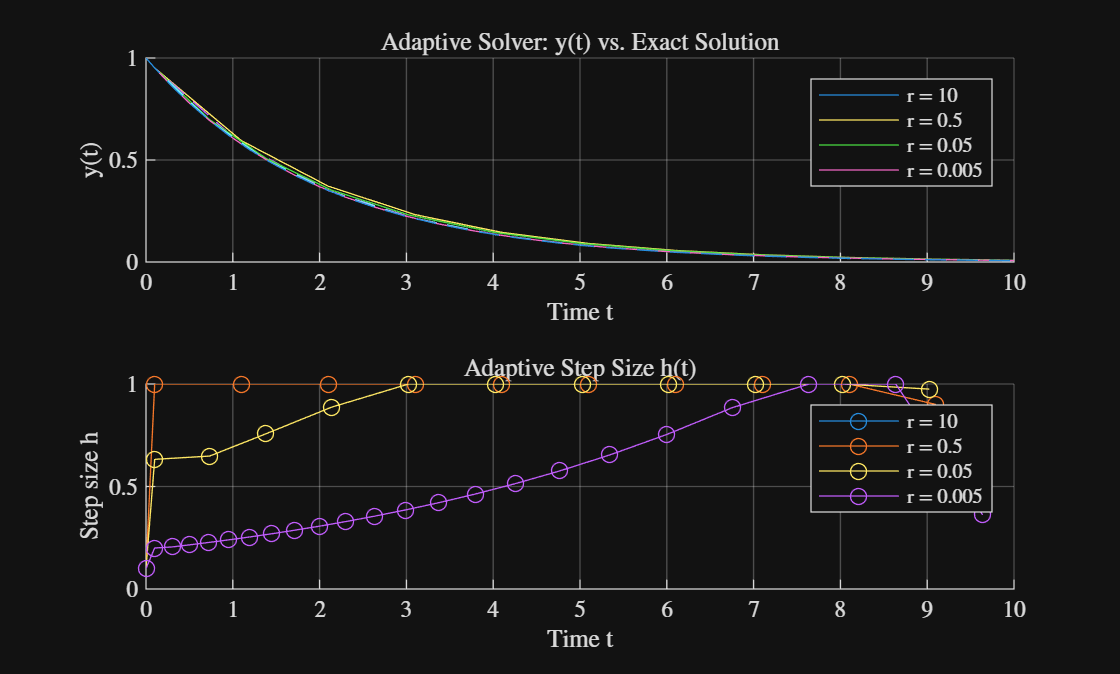


% Parameters
r_values = [10, 0.5, 0.05, 0.005];

figure;
tiledlayout(2,1);

nexttile;
hold on; grid on;
title('Adaptive Solver: y(t) vs. Exact Solution');

nexttile;
hold on; grid on;
title('Adaptive Step Size h(t)');
xlabel('Time t');

for r = r_values
    [t, y, h_values] = adaptive_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                                       PARAMETERS.t_0, PARAMETERS.t_final, r);

    % Exact solution for comparison
    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

    % --- Plot results ---
    nexttile(1);
    plot(t, y, 'DisplayName', ['r = ', num2str(r)]);
    plot(t, y_exact, '--', 'HandleVisibility', 'off');

    nexttile(2);
    plot(t(1:end-1), h_values, '-o', 'DisplayName', ['r = ', num2str(r)]);
end

nexttile(1);
xlabel('Time t');
ylabel('y(t)');
legend('Location','northeast');

nexttile(2);
ylabel('Step size h');
legend('Location','northeast');

for r = [0.005, 0.05, 0.5, 5, 10]
    [t, y, h_values] = adaptive_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                                       PARAMETERS.t_0, PARAMETERS.t_final, r);
    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);
    global_rel_error = mean(abs((y - y_exact)./y_exact)) * 100;
    fprintf('r = %.3f  ->  mean global rel. error = %.3f %%  | steps = %d\n', ...
            r, global_rel_error, length(h_values));
end

r = 0.005  ->  mean global rel. error = 2.302 %  | steps = 23
r = 0.050  ->  mean global rel. error = 10.539 %  | steps = 12
r = 0.500  ->  mean global rel. error = 15.216 %  | steps = 11
r = 5.000  ->  mean global rel. error = 15.216 %  | steps = 11
r = 10.000  ->  mean global rel. error = 15.216 %  | steps = 11



function [t_values, y_values, h_values] = adaptive_solver(y0, tau, t0, t_final, r)
    % Initial values
    t = t0;
    y = y0;
    h = 0.1;              % initial step
    h_min = 1e-5;         % lower limit to avoid endless loop
    h_max = 1.0;          % optional safety upper limit

    % Function handle for ODE
    f = @(t, y) -y / tau;

    % Storage arrays
    t_values = t;
    y_values = y;
    h_values = [];

    % Integration loop
    while t < t_final
        if t + h > t_final
            h = t_final - t;  % adjust last step
        end

        % ---- Step 1: Euler & Midpoint ----
        y_euler = y + h * f(t, y);
        y_mp = y + h * f(t + h/2, y + (h/2) * f(t, y));

        % ---- Step 2: Local error estimate ----
        eps_loc = abs(y_mp - y_euler);

        % ---- Step 3: Step-size control ----
        if eps_loc < r
            % Accept step
            t = t + h;
            y = y_mp;                 % accept midpoint result
            t_values(end+1) = t;
            y_values(end+1) = y;
            h_values(end+1) = h;

            % Update next step size (smooth scaling)
            h = min(h * sqrt(r / max(eps_loc, eps)), h_max);
        else
            % Reject step, reduce h and retry
            h = max(h * sqrt(r / max(eps_loc, eps)), h_min);
        end
    end
end